clf

% boilerplate / global specs
mm_to_m = 1/1000;
thickness = 9.1*mm_to_m; %4.4*mm_to_m;
width = 40*mm_to_m;

constants = containers.Map;
constants('youngs_mod') = 29*10^9;%5*10^9%25*10^9 %29*10^9;%250*10^9; 91GPa Williams
constants('shear_mod') = 10*10^9;%1.9*10^9%10*10^9;
constants('shape_factor') = 6/5;

forces = containers.Map();
F = 3800;
Fa = pi-(7*pi/180);
V = F*sin(Fa); 
H = F*cos(Fa);
forces('f') = [V; H];

s1 = containers.Map;
s1('thickness') = thickness;
s1('length') = (100.12*2/5)*mm_to_m;
s1('width') = width;
s1('beam_angle') = 0.476; %*(pi/180); % rad
s1('couple') = 0; % init
s1('boundary_angle') = 0;
s1('boundary_defV') = 0;
s1('boundary_defH') = 0;
straight1 = Straight(constants, s1);

% FOR A CURVED SECTION, THE  start_angle IS THE LOADED END
c1 = containers.Map();
c1('thickness') = thickness;
c1('width') = width;
c1('radius') = (33.2/2)*mm_to_m; %m
c1('end_angle') = -pi/2+0.476;
% c1('end_angle') = -0.996;
c1('start_angle') = 0.15;
c1('boundary_angle') = 0;
c1('boundary_defV') = 0;
c1('boundary_defH') = 0;
c1('couple') = 0; % init
curved1 = Curved(constants, c1);

chonk



c2 = containers.Map();
c2('thickness') = thickness;
c2('width') = width;
c2('radius') = (104/2)*mm_to_m; %m
c2('start_angle') = 0.43;
c2('end_angle') = 0.15;
c2('boundary_angle') = 0;
c2('boundary_defV') = 0;
c2('boundary_defH') = 0;
c2('couple') = 0; % init
curved2 = Curved(constants, c2);

chonk



sections = containers.Map();
sections('3') = curved2;
sections('2') = curved1;
sections('1') = straight1;

% implement force sweep where range input is magnitude and angle sweep
% [x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch_sweep(sections, forces, 'thickness', 5, [6*mm_to_m, 10*mm_to_m], 'linspace');
[x_base, y_base, x_deformed, y_deformed, moment, ang, strain_e, stiffness] = stitch(sections, forces, 'linspace');
disp(stiffness)

$$1732.0804944921688425305466315724$$

abs_deflection = vpa(sqrt((x_base(end)-x_deformed(end))^2+(y_base(end)-y_deformed(end))^2));
disp(abs_deflection*100)

$$0.47940270329987921488100526825724$$

disp("cm")

cm


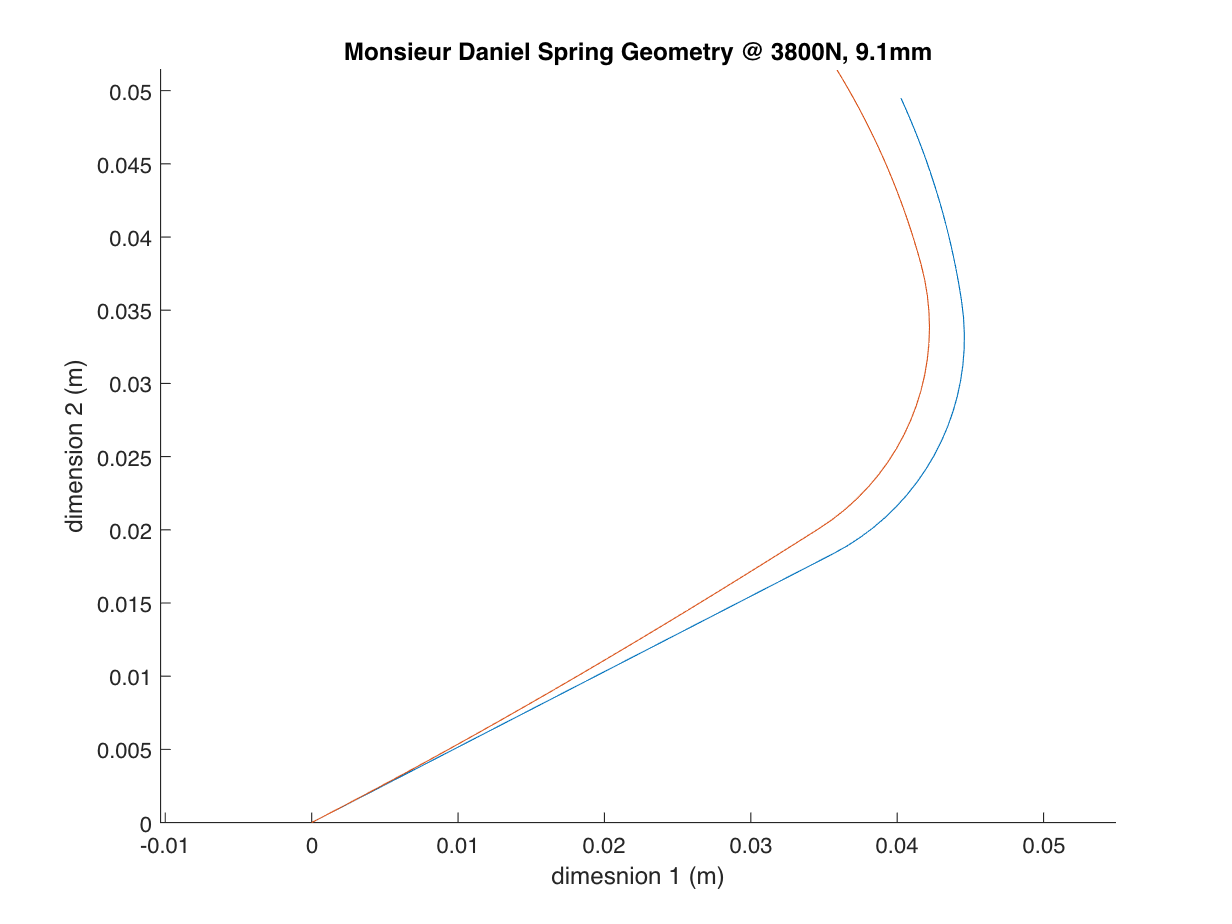

hold on
axis('equal')
plot(x_base, y_base)
plot(x_deformed, y_deformed)
title('Monsieur Daniel Spring Geometry @ 3800N, 9.1mm')
xlabel('dimesnion 1 (m)')
ylabel('dimension 2 (m)')

hold off
axis('auto')

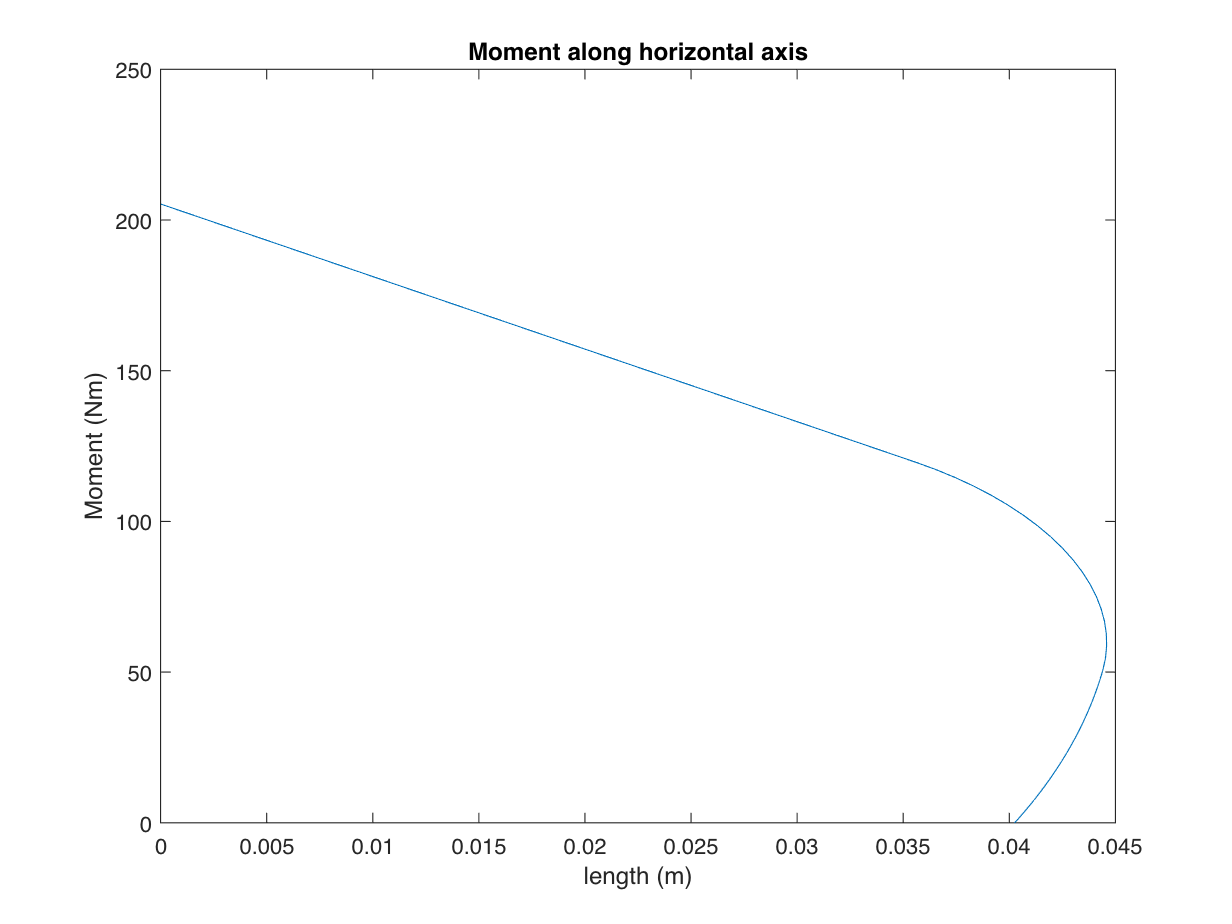

plot(x_base, moment)
title('Moment along horizontal axis')
xlabel('length (m)')
ylabel('Moment (Nm)')

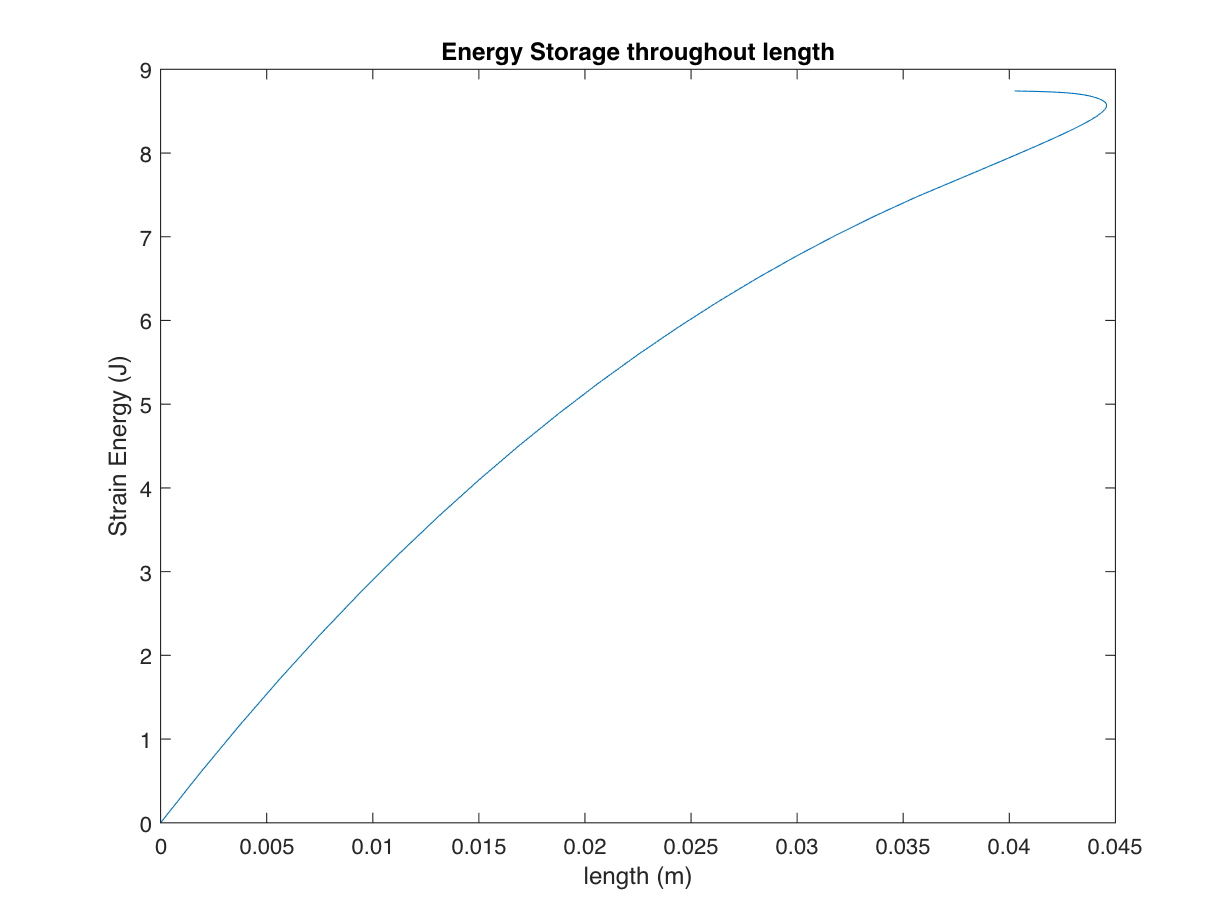

plot(x_base, strain_e)
title('Energy Storage throughout length')
xlabel('length (m)')
ylabel('Strain Energy (J)')

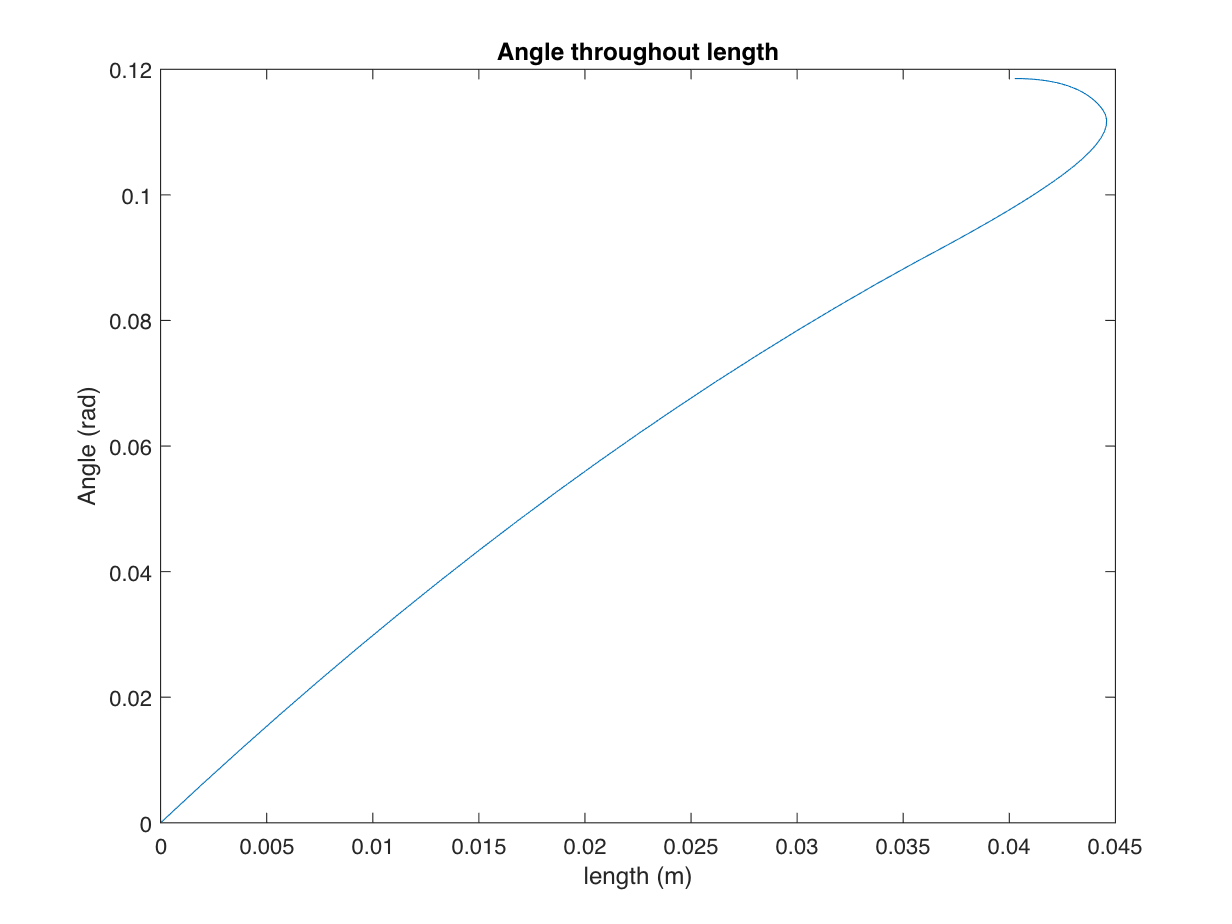

plot(x_base, ang)
title('Angle throughout length')
xlabel('length (m)')
ylabel('Angle (rad)')